# Math 244: MATLAB Assignment 5

### Name: Kym Derriman

### RUID: kad424

### Date: 10/27/2024

clear;
clc;

## 1. 

% omega = 1;
% Af = -1/5;
% Ac = 1 - A_f = 1.2;
% As = -2/omega = -2;



## 2.

% Run secondundampedsolver with the appropriate coefficients

B = 1;
A = 3;
omegaf = 4;
y0 = 1;
v0 = 2;

% By hand:


[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0);

fprintf('Ac = %.2f\n', Ac);

Ac = 1.20


fprintf('As = %.2f\n', As);

As = 2.00


fprintf('omegas = %.2f\n', omegas);

omegas = 1.00


fprintf('Af = %.2f\n', Af);

Af = -0.20



$$\frac{d^2y}{dt^2} + B y = A \cos(\omega_f t)$$



$$y(t) = \left( y_0 - \frac{A}{B - \omega_f^2} \right) \cos(\sqrt{B} t) + \frac{v_0}{\sqrt{B}} \sin(\sqrt{B} t) + \frac{A}{B - \omega_f^2} \cos(\omega_f t)$$


## 3.

% Coefficients 1
B = 9;
A = 1;
omegaf = 4;
y0 = 0;
v0 = 0;

[~, ~, ~, Af] = secondUndampedSolver(B, A, omegaf, y0, v0);
fprintf('Af = %.2f\n', Af);

Af = -0.14


The natural frequency is the square root of 9. w0^2 = 9 --- w0 = 3.

% Coefficients 2
omegaf = 3.1;

[~, ~, ~, Af] = secondUndampedSolver(B, A, omegaf, y0, v0);
fprintf('Af = %.2f\n', Af);

Af = -1.64


% Coefficients 3

omegaf = 3.01;

[~, ~, ~, Af] = secondUndampedSolver(B, A, omegaf, y0, v0);
fprintf('Af = %.2f\n', Af);

Af = -16.64


% Coefficients 4

omegaf = 3;

[~, ~, ~, Af] = secondUndampedSolver(B, A, omegaf, y0, v0);
fprintf('Af = %.2f\n', Af);

Af = Inf


The forced response approaches infinity as omegaf approaches 3. $\lim_{\omega_f \to 3} A_f ~ = ~ \infty$

## 4.

A = 1;
B = 9;
omegaf = 3;
y0 = 0;
v0 = 0;

[~, ~, ~, Af] = secondUndampedSolver(B, A, omegaf, y0, v0);
fprintf('Af = %.2f\n', Af);

Af = Inf


The general solution shown below found by hand leads to the same ultimate result as that found by the solver function. In both cases the forced responce approaches infinity as t grows. The distinction is in the unique characteristics of the solution found by hand. It gives the specifics about exactly how this resonance will grow with time, in this case, linearly with a scaling factor of 1/6th. The solution function just gives you the end result I guess. I suppose we could modify it to give the unique expression as well.

As far as what the question in the lab guide asks, "Why didn't the secondUndampedSolver method work properly?" well, I think it did work properly insofar as it tells you what the system does over a lengthy period of time. Maybe I'm missing something?


$$y(t) = \frac{t}{6} ~ \sin(3t)$$


## 5.

% Solves second order ODE symbolically

syms y(t);
Dy = diff(y);

ode = diff(y,t,2) + 9*y == cos(3*t);
cond1 = y(0) == 0;
cond2 = Dy(0) == 0;

conds = [cond1 cond2];
ySol(t) = dsolve(ode,conds);
ySol = simplify(ySol)

$$ySol(t) = \frac{t\,\sin\left(3\,t\right)}{6}$$

This outputs the same solution I got by hand.

## 6.

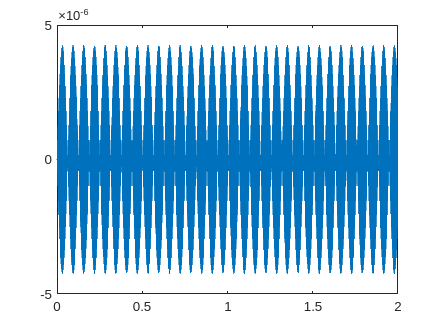

tVals = linspace(0,2, 2*8192);

% Use second undamped solver to get the coefficients

B = 2400^2;
A = 1;
omega = 2300;
y0 = 0;
v0 = 0;

[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omega, y0, v0);

% Put the coefficients together in an anonymous function
sol1 = @(t) Ac * cos(omegas*t) + As*sin(omegas*t) + Af*cos(omega*t);

figure()
plot(tVals, sol1(tVals));


%sound(sol1(tVals));

% Scale the solution function to be within -1 to 1 for sound playback
scaledSolution = sol1(tVals) * 1e7;  % Scaling to make the amplitude larger

% Play the scaled sound
sound(scaledSolution, 8192); % Assuming a sampling rate of 8192 Hz


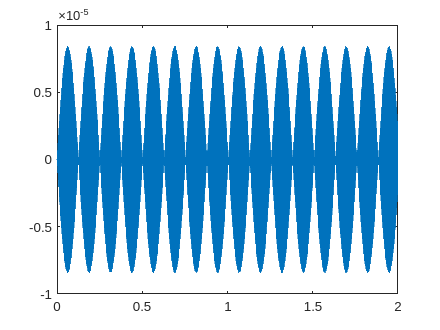

% Repeat for this new omega 

B = 2400^2;
A = 1;
omega = 2350;
y0 = 0;
v0 = 0;

[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omega, y0, v0);

% Put the coefficients together in an anonymous function
sol1 = @(t) Ac * cos(omegas*t) + As*sin(omegas*t) + Af*cos(omega*t);

figure()
plot(tVals, sol1(tVals));


%sound(sol1(tVals));

% Scale the solution function to be within -1 to 1 for sound playback
scaledSolution = sol1(tVals) * 1e7;  % Scaling to make the amplitude larger

% Play the scaled sound
sound(scaledSolution, 8192); % Assuming a sampling rate of 8192 Hz


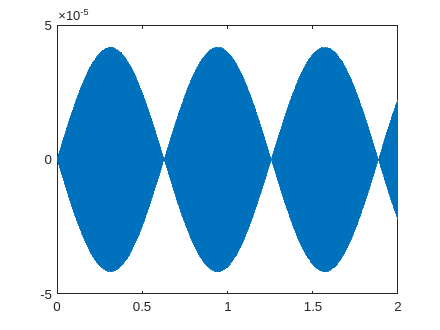

% Repeat for this new omega 

B = 2400^2;
A = 1;
omega = 2390;
y0 = 0;
v0 = 0;

[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omega, y0, v0);

% Put the coefficients together in an anonymous function
sol1 = @(t) Ac * cos(omegas*t) + As*sin(omegas*t) + Af*cos(omega*t);

figure()
plot(tVals, sol1(tVals));


%sound(sol1(tVals));

% Scale the solution function to be within -1 to 1 for sound playback
scaledSolution = sol1(tVals) * 1e7;  % Scaling to make the amplitude larger

% Play the scaled sound
sound(scaledSolution, 8192); % Assuming a sampling rate of 8192 Hz


As omega gets closer to 2400, the wavelength spreads out, increasing in length, the amplitude grows, and the sound becomes less "busy" for lack of a better word. It sounds more clear and you're able to hear the tone without a lot of "wobbles." Not sure what to call it.

## 7. 

syms y1(t);
Dy1 = diff(y1);

ode1 = diff(y1,t,2) + diff(y1,t,1) +16*y1 == 0;
cond1 = y1(0) == 10;
cond2 = Dy1(0) == 0;

conds = [cond1 cond2];
ySol1(t) = dsolve(ode1,conds);
ySol1 = simplify(ySol1);

syms y2(t);
Dy2 = diff(y2);

ode2 = diff(y2,t,2) + 10*diff(y2,t,1) +16*y2 == 0;
cond1 = y2(0) == 10;
cond2 = Dy2(0) == 0;

conds = [cond1 cond2];
ySol2(t) = dsolve(ode2,conds);
ySol2 = simplify(ySol2);


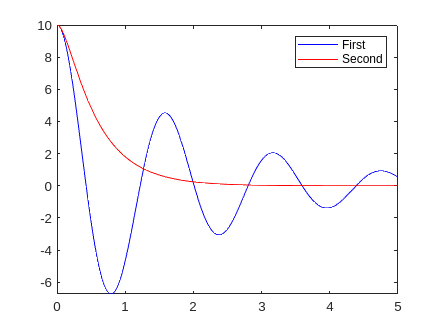

figure(5);
fplot(ySol1, [0,5],'b');
hold on;
fplot(ySol2, [0,5],'r');
legend('First', 'Second');
hold off;

It's pretty clear that the red line which plots the second equation is the one that represents molasses. There is no oscillation. This makes sense as there is a multiple of 10 in front of the camping coefficient, which means that the energy of the system will dissipate much more rapidly. This also makes sense intuitively if one imagines a pendulum in molasses. It would just kind of sink to the equilibrium position very slowly.

function [Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0)

    Af = A/(B - omegaf^2);
    Ac = y0-Af;
    omegas = sqrt(B);
    As = v0/omegas;
    
end